# Observador

clear; close all; clc; 
addpath("data/");
addpath("data/tests");
load("DatosStepsVariables.mat"); 
theta_0 = 89;  % inicial
[sys, ~, ~, ~] = FoundTF(theta_0); 
load("data/TF.mat"); 

% Variables de estado 
A = sys.A; 
B = sys.B; 
C = sys.C; 
D = sys.D; 

% Matrices de ponderacion 
qx1 = 100; 
qx2 = 1000000; 
r = 1; 

Q = [qx1 0  ;0 qx2];
R = r; 

% Diseño de lqr 
[L, S, P] = lqr(A', C', Q, R); 
L = L'

L =    42.6055
  857.6136


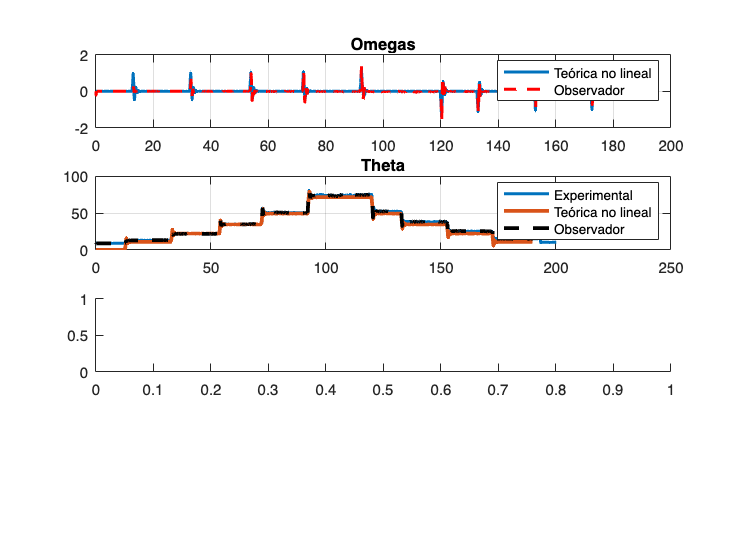


Ahat = A-L*C;
Bhat = [B L];
Chat = eye(2);
Dhat = [0];

SysHat = ss(Ahat,Bhat,Chat,Dhat);
SysHat.StateName = {'thetaHat','omegaHat'};
SysHat.OutputName = {'thetaHat','omegaHat'};
SysHat.InputName = {'PWM','theta'};
Observer = c2d(SysHat,2.5e-3,'tustin'); % Implementacion en arduino

save('data/observer.mat',"L", "SysHat");
save('../implementacion/data/observer.mat', "L", "Observer"); 

addpath("sims/");
data = sim("sims/observer", 190); % Simulacion 

t = data.tout; 
% Velocities
omega = data.omega.Data ; 
omega_hat = data.omega_hat.Data;
omega_SS = data.omegaSS.Data;

% Angles 
theta = data.theta.Data ; 
theta_hat = data.theta_hat.Data ; 
theta_exp = data.theta_exp.Data; 
theta_SS = data.thetaSS.Data;

subplot(4, 1, 1); 
plot(t, omega, t, omega_hat, "r--", "LineWidth", 2); 
title("Omegas")
legend("Teórica no lineal", "Observador"); 
grid on; 

subplot(4, 1, 2); 
plot(DatosStepsVariables(:,1), DatosStepsVariables(:,3), "LineWidth", 2); 

hold on; 
plot(t, theta, t, theta_hat, "k--", "LineWidth", 2.5); 
hold off; 

title("Theta")
legend("Experimental", "Teórica no lineal", "Observador" ); 
grid on; 

subplot(4,1,3)

plot(t, omega_hat, t, omega_SS, "r--", "LineWidth", 0.5); 

Error using plot
Vectors must be the same length.

subplot(4,1,4)
plot(t,theta_hat,t,theta_SS, "r--", "LineWidth", 0.5)


## Implementación Arduino

L
s = tf('s')
integrador =  1/s;
intDiscrete = c2d(integrador,2.5e-3,'tustin')

sys